## NDVI POR ESTACION

### NDVI del año 2000 al 2022

### 1.- Inicialización de la información

Imports y declaración de variables

import matlab.io.hdfeos.*

clearvars -except area_estudio;
close all;

Declaracón de variables como directorio de datos, latitud y longitud del área de estudio y posición en las cuadriculas de MODIS. 

declaraciones

>>> Declarando variables...ok


Variables para realizar seguimiento del código y mostrar más mensajes y/o mapas. Tiempo de pausa en segundos.

debug_pausa = 2; %tiempo de pausa de imagenes
debug_dibujar_mapa = false;  %dibujar los mapas 

Leer todos los archivos de la zona de estudio y guardar la información en una tabla

| idx | diaj | dia | mes | estación | año | v6 | v7 | calidad |

%% obtener la info del área de estudio
[lat,lon,ndvi] = m_leer_dir_hdfs(dir_data,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos


info_hdf = m_infohdfs2table(dir_data);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos


Matriz que delimita el área de estudio. Se carga de archivo "area_estudio.mat". Sino existe. Lo crea. El proceso puede tardar un rato

ae = exist("area_estudio","var");
if ae == 0
    ae = exist("area_estudio.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load area_estudio;
    else
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
        
    end
else
    if( numel(area_estudio) <= 1)
        disp("La variable area_estudio sera sustituida");
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
end

Pixeles en total del área de estudio

calidad_total = sum(area_estudio,"all");

Dibujar mapa de prueba de lectura de datos

% if debug_dibujar_mapa == true
%     ndvi(area_estudio==false)=NaN;
%     m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI TEST",[],ndvi_colormap,"NDVI");
%     m_dibujar_kml(dir_data,"RH26",1,'b',"RH26")
%     pause(debug_pausa);
% end 

### 2.- Declarar variables para obtener la información por estación

% Los años que se desean consultar
estaciones = 1:4;

% Arreglo donde se almacenara el promedio de NDVI por año
tabla_promedio_estaciones =zeros(1,length(estaciones));
tabla_desvEst_estaciones =zeros(1,length(estaciones));

% Arreglo en 3d
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,length(estaciones));

lbl_estaciones = ["Primavera","Verano","Otoño","Invierno"];

### 3.- Recuperar la información y crear las matrices de 3 dimensiones

Recuperar  la información


for a = 1:length(estaciones)

        tmp =  find(  info_hdf.estacion == estaciones(a)  );
        img_fechas_consulta = info_hdf(tmp,:);
        [filas,~] = size(img_fechas_consulta);
        disp("Estación: "+estaciones(a) +". No de archivos: "+filas);
        
        %arreglo de promedios de las imagenes
        arr_promedio_estaciones = zeros(1,filas);
        arr_ndvi_estaciones  = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);
        
        % obtener la info de un año
        bp=waitbar(0,'Obteniendo información: '+lbl_estaciones(a)+" ("+a+"/4)"); 

        for i=1:filas
                    waitbar(i/filas,bp);

            %disp("Analizando "+i+" de "+filas);
            [ndvi,~,~,disponibilidad] = m_obtener_ndvi(dir_data,img_fechas_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
        
            % recortar el area de estudio
            ndvi(area_estudio==false)=NaN;
            disponibilidad(area_estudio==false)=NaN;

            %omitir las zonas con nubes o nieve
            ndvi (disponibilidad>1)=NaN;
            disponibilidad(disponibilidad>1)=NaN;
        
            calidad = m_calidad_imagen(disponibilidad,calidad_total);
        
            % promedio ndvi si es de buena calidad, sino nan
            if calidad >=95
                promedio_ndvi = mean(ndvi,'all','omitnan');
                arr_promedio_estaciones(i) = promedio_ndvi;
                arr_ndvi_estaciones(:,:,i) = ndvi;
            else
                arr_promedio_estaciones(i) = nan;
                arr_ndvi_estaciones(:,:,i) = nan;
            end
   
        end
        close(bp); 
    tabla_promedio_estaciones(a) = mean(arr_promedio_estaciones,"all","omitnan");
    tabla_desvEst_estaciones(a) = std(arr_promedio_estaciones,0,"all","omitnan");

    arr_ndvi(:,:,a) = m_mean_3dpp(arr_ndvi_estaciones);

    if debug_dibujar_mapa == true 
        % dibujar el mapa
        m_dibujar_mapa_ndvi(lon_proyeccion,lat_proyeccion,lon,lat,ndvi_promedio_anio,"RH 26 ("+img_fechas_consulta.anio(i)+")",1);
        m_dibujar_otras_areas(dir_data,"RH26_prom_anio_"+img_fechas_consulta.estacion(i)+"-)");
        pause (debug_pausa);
        
    end
end

Estación: 1. No de archivos: 135
Estación: 2. No de archivos: 138
Estación: 3. No de archivos: 138
Estación: 4. No de archivos: 110


### 4.- Usar los datos obtenidos 

Mostrar el promedio por día de NDVI 

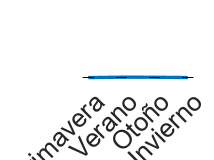

figure;

plot(estaciones,tabla_promedio_estaciones,'LineWidth',2);
%title('NDVI promedio x estación');
xlabel('Estación');
xticks(1:4);
xticklabels(lbl_estaciones);
ylabel('Promedio NDVI');
xlim([0.8 4.2]);
ylim([0.3 0.7]);

hold on

er=errorbar(estaciones,tabla_promedio_estaciones,tabla_desvEst_estaciones); 
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off
ax = gca;
ax.FontSize=16; 

exportgraphics(gca,"img/g_promedio_x_año.png",'Resolution',300) 

### 5. Mostrar el promedio de un año en particular

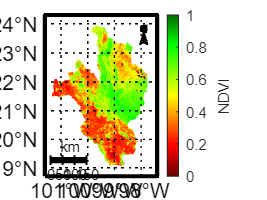

estacion = 4;

m_dibujar_mapa_ndvi(lon_mapa,lat_mapa,lon,lat,arr_ndvi(:,:,estaciones==estacion),"NDVI promedio de "+lbl_estaciones(estacion),0);
%m_dibujar_otras_areas(dir_data);

exportgraphics(gca,"img/m_promedio_x_estacion_"+estacion+"_"+lbl_estaciones(estacion)+".png",'Resolution',300) 